clear all; close all

legend_names = {'motor';'load'}

legend_names = 2×1 cell array
    {'motor'}
    {'load' }



%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04


%loading experiment data
load("experiment_26_3.mat")
u1 = u; d1 = d;
load("experiment_26_3_LOADSIDE.mat")
u2 = u; d2 = d; %writing data to unique names
clear u d %clearing unused data

%removing useless data 
N_trash = 1000; 
u1 = u1(N_trash:end); d1 = d1(N_trash:end)

d1 =    -0.9298
   -0.1881
    0.9806
    0.5293
    0.0130
    0.0297
    0.1451
   -0.3181
   -0.1558
   -0.6957


u2 = u2(N_trash:end); d2 = d2(N_trash:end)

d2 =     0.2999
   -0.1343
    0.4455
   -0.8925
    0.9417
   -0.1279
   -0.4596
    0.1976
   -0.1780
    0.1818



%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds
nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/5);

%Tf estimate
[S1, F1] = tfestimate(d1,u1,hann(nfft),n_overlap,nfft,fs); %cross spectral power density
[S2, F2] = tfestimate(d2,u2,hann(nfft),n_overlap,nfft,fs); %cross spectral power density

%{
figure()
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on; hold off

figure()
semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on; hold off
%}

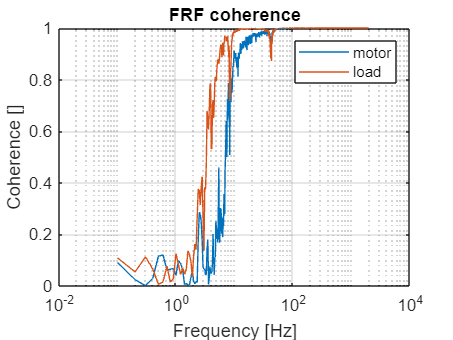


%plotting coherence 
fig = figure();
[cxy, f] = mscohere(d1,u1,hann(nfft),n_overlap,nfft,fs);
semilogx(f, cxy)
hold on
[cxy, f] = mscohere(d2,u2,hann(nfft),n_overlap,nfft,fs);
semilogx(f,cxy)
title('FRF coherence')
xlabel('Frequency [Hz]')
ylabel('Coherence []')
legend(legend_names)
grid on; hold off

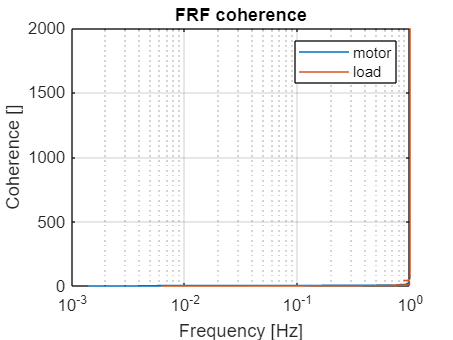


saveas(fig,'system_coherence.png')


%plotting open loop transfer function
L1 = 1./S1 - 1;
L2 = 1./S2 - 1;

f = figure()

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


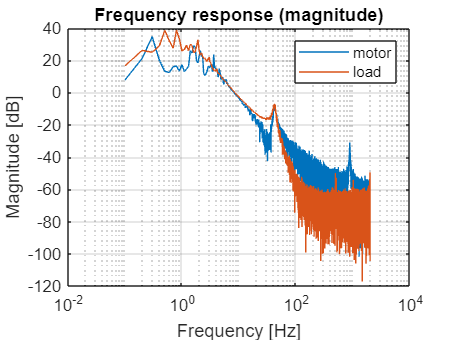

semilogx(F1,mag2db(abs(L1)))
hold on
semilogx(F2,mag2db(abs(L2)))
title('Frequency response (magnitude)')
xlabel("Frequency [Hz]")
ylabel("Magnitude [dB]")
legend(legend_names)
grid on; hold off
saveas(f,'system_magnitude_response.png')


f = figure()

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


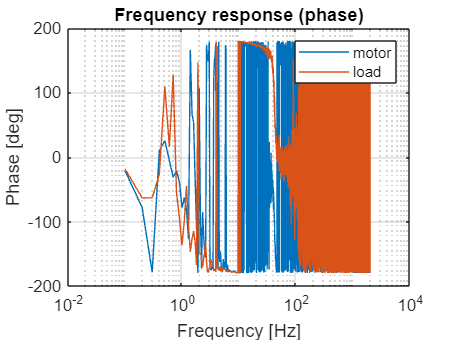

semilogx(F1,angle(L1)/pi*180)
hold on 
semilogx(F2,angle(L2)/pi*180)
title('Frequency response (phase)')
xlabel('Frequency [Hz]')
ylabel('Phase [deg]')
legend(legend_names)
grid on; hold off
saveas(f,'System_phase_response.png')